## **Espace de solutions**

### **Recuperation des solutions calculées dans le fichier ***Config_Robot_Redondant_Point*

% Charger les solutions depuis le fichier
load('solutions.mat');
% Afficher toutes les configurations trouvées en radian
disp('Configurations possibles du robot en rad pour la position désirée :');

Configurations possibles du robot en rad pour la position désirée :


disp('    Theta1   Theta2    Theta3    Theta4    Theta5  X_calculé   Y_calculé');

    Theta1   Theta2    Theta3    Theta4    Theta5  X_calculé   Y_calculé


disp(all_solutions);  

    5.7395    0.9919    5.8750    0.2334    0.3178   10.0000    2.0000
    5.8564    0.9145    5.7502    0.1677    0.5648   10.0000    2.0000
    6.0639    0.8805    5.4486    0.1257    0.5906   10.0000    2.0000
    0.1484    0.4755    6.0303    6.0225    5.6526   10.0000    2.0000
    0.2183    6.0746    0.7830    5.0975    0.8485   10.0000    2.0000
    0.2222    0.4299    5.8288    5.5633    0.6949   10.0000    2.0000
    5.9976    0.8072    5.8641    5.9699    0.9069   10.0000    2.0000
    6.0140    0.9605    5.5334    6.2471    0.5756   10.0000    2.0000
    0.3538    0.3972    5.4149    6.1652    0.2159   10.0000    2.0000
    6.0164    0.5411    0.3539    5.3570    0.8959   10.0000    2.0000
    0.1998    0.2468    0.1551    5.7973    5.6113   10.0000    2.0000
    6.2234    0.8196    5.2188    0.3571    0.2247   10.0000    2.0000
    5.7778    0.5309    0.4399    0.0178    0.0787   10.0000    2.0000
    5.8931    0.6338    0.0571    5.9574    0.8689   10.0000    2.0000
    5.

    

% Convertion des angles de radians en degrés et afficher les résultats
all_solutions_deg = rad2deg(all_solutions(:, 1:5));
% Afficher toutes les configurations trouvées en degrrs
disp('Configurations possibles du robot en degres pour la position désirée :');

Configurations possibles du robot en degres pour la position désirée :


disp('    Theta1°   Theta2°   Theta3°   Theta4°  Theta5°   X_calculé   Y_calculé')

    Theta1°   Theta2°   Theta3°   Theta4°  Theta5°   X_calculé   Y_calculé


disp([all_solutions_deg, all_solutions(:, 6:7)]);

  328.8476   56.8314  336.6136   13.3710   18.2080   10.0000    2.0000
  335.5478   52.3950  329.4599    9.6076   32.3591   10.0000    2.0000
  347.4350   50.4503  312.1800    7.2027   33.8374   10.0000    2.0000
    8.5033   27.2445  345.5132  345.0655  323.8717   10.0000    2.0000
   12.5067  348.0465   44.8611  292.0634   48.6137   10.0000    2.0000
   12.7309   24.6312  333.9631  318.7522   39.8152   10.0000    2.0000
  343.6355   46.2488  335.9888  342.0515   51.9600   10.0000    2.0000
  344.5762   55.0304  317.0407  357.9313   32.9797   10.0000    2.0000
   20.2686   22.7567  310.2483  353.2379   12.3698   10.0000    2.0000
  344.7160   31.0037   20.2784  306.9331   51.3296   10.0000    2.0000
   11.4459   14.1428    8.8843  332.1629  321.5016   10.0000    2.0000
  356.5767   46.9613  299.0133   20.4626   12.8728   10.0000    2.0000
  331.0411   30.4184   25.2029    1.0189    4.5066   10.0000    2.0000
  337.6504   36.3113    3.2690  341.3340   49.7816   10.0000    2.0000
  329.

 

% Convertir les angles en radians et ajuster les angles à l'intervalle [-180, 180]
all_solutions_deg = mod(all_solutions_deg + 180, 360) - 180;
% Afficher toutes les configurations trouvées en degrrs
disp('Configurations possibles du robot en degres dans intervalle -180 180 :');

Configurations possibles du robot en degres dans intervalle -180 180 :


disp('    Theta1°   Theta2°   Theta3°   Theta4°  Theta5°   X_calculé   Y_calculé')

    Theta1°   Theta2°   Theta3°   Theta4°  Theta5°   X_calculé   Y_calculé


disp([all_solutions_deg, all_solutions(:, 6:7)]);

  -31.1524   56.8314  -23.3864   13.3710   18.2080   10.0000    2.0000
  -24.4522   52.3950  -30.5401    9.6076   32.3591   10.0000    2.0000
  -12.5650   50.4503  -47.8200    7.2027   33.8374   10.0000    2.0000
    8.5033   27.2445  -14.4868  -14.9345  -36.1283   10.0000    2.0000
   12.5067  -11.9535   44.8611  -67.9366   48.6137   10.0000    2.0000
   12.7309   24.6312  -26.0369  -41.2478   39.8152   10.0000    2.0000
  -16.3645   46.2488  -24.0112  -17.9485   51.9600   10.0000    2.0000
  -15.4238   55.0304  -42.9593   -2.0687   32.9797   10.0000    2.0000
   20.2686   22.7567  -49.7517   -6.7621   12.3698   10.0000    2.0000
  -15.2840   31.0037   20.2784  -53.0669   51.3296   10.0000    2.0000
   11.4459   14.1428    8.8843  -27.8371  -38.4984   10.0000    2.0000
   -3.4233   46.9613  -60.9867   20.4626   12.8728   10.0000    2.0000
  -28.9589   30.4184   25.2029    1.0189    4.5066   10.0000    2.0000
  -22.3496   36.3113    3.2690  -18.6660   49.7816   10.0000    2.0000
  -30.

### **Variation de theta pour chaque solution**

% Définir le nombre total de solutions
num_solutions = size(all_solutions, 1);
% Définir le nombre de lignes et de colonnes pour la grille
num_rows = 3; % Modifier le nombre de lignes selon le nombre de joints
num_cols = 2; % Nombre de colonnes pour afficher les graphiques
% Définir les positions des subplots
position = reshape(1:num_rows*num_cols, num_cols, num_rows).';

% Convertir les angles en degrés et ajuster les angles à l'intervalle [-180, 180]
all_solutions_deg = rad2deg(all_solutions(:, 1:5));
all_solutions_deg = mod(all_solutions_deg + 180, 360) - 180;

% Créer une nouvelle figure
figure;

% Boucle sur chaque angle d'articulation
for joint = 1:5
    % Définir la position du subplot dans la grille
    subplot(num_rows, num_cols, joint);
    
    % Titre et étiquettes des axes
    title(['Variation de Theta', num2str(joint), ' pour chaque solution']);
    xlabel('Solution');
    ylabel(['Theta', num2str(joint), '°']); % Modification de l'étiquette en degrés
    grid on;

    hold on; % Garder le graphique actif pour ajouter les données de chaque solution

    % Tracer les valeurs des angles d'articulation pour chaque solution
    for i = 1:num_solutions
        % Extraire l'angle d'articulation ajusté pour cette solution
        theta_deg = all_solutions_deg(i, joint);

        % Tracer l'angle d'articulation pour cette solution
        plot(i, theta_deg, '+', 'MarkerSize', 5, 'LineWidth', 1, 'Color', 'k','HandleVisibility', 'off');
    end

    % Calculer une interpolation linéaire des données
    x_data = 1:num_solutions; % Les données x sont simplement les indices des solutions
    y_data = all_solutions_deg(:, joint); % Les données y sont les angles d'articulation déjà ajustés

    % Définir un ensemble de points plus fins pour l'interpolation
    finer_x = linspace(1, num_solutions, 1000); % 1000 points entre le premier et le dernier index

    % Calculer les valeurs interpolées
    interpolated_1 = interp1(x_data, y_data, finer_x, 'spline');
    interpolated_2 = interp1(x_data, y_data, finer_x, 'linear');

    % Tracer la courbe d'interpolation
    plot(finer_x, interpolated_1, 'r-', 'LineWidth', 1, 'DisplayName', 'Interpolation Spline');
    plot(finer_x, interpolated_2, 'k-', 'LineWidth', 1, 'DisplayName', 'Interpolation Lineaire');

    % Trouver la valeur maximale et minimale de theta pour cet angle d'articulation
    max_theta = max(all_solutions_deg(:, joint));
    min_theta = min(all_solutions_deg(:, joint));
    
    % Ajouter du texte à la position souhaitée
    text(-1, max_theta, ['Max: ', num2str(max_theta)], 'Color', 'blue', 'FontSize', 8);
    text(-1, min_theta, ['Min: ', num2str(min_theta)], 'Color', 'blue', 'FontSize', 8);
    disp(['Pour theta', num2str(joint), ', Theta max : ', num2str(max_theta), ', Theta min : ', num2str(min_theta)]);

    % Tracer une droite représentant la valeur maximale de theta pour cet angle d'articulation
    plot([1, num_solutions], [max_theta, max_theta], '-b', 'LineWidth', 0.6, 'DisplayName', ['Max Theta', num2str(joint)]);

    % Tracer une droite représentant la valeur minimale de theta pour cet angle d'articulation
    plot([1, num_solutions], [min_theta, min_theta], '-b', 'LineWidth', 0.6, 'DisplayName', ['Min Theta', num2str(joint)]);
      
end

Pour theta1, Theta max : 20.2686, Theta min : -31.1524
Pour theta2, Theta max : 56.8314, Theta min : -11.9535
Pour theta3, Theta max : 44.8611, Theta min : -60.9867
Pour theta4, Theta max : 20.4626, Theta min : -67.9366
Pour theta5, Theta max : 51.96, Theta min : -38.4984


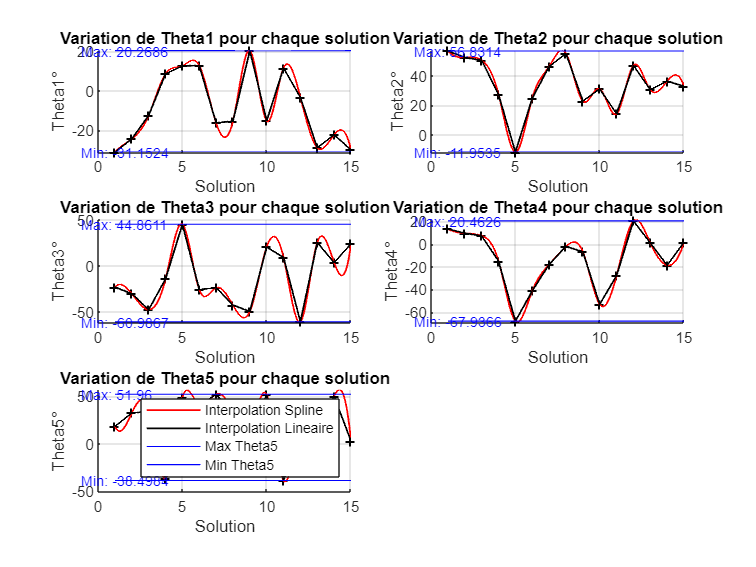


% Légende
legend('show');

#### Courbe des angles pour chaque solution - interpolation

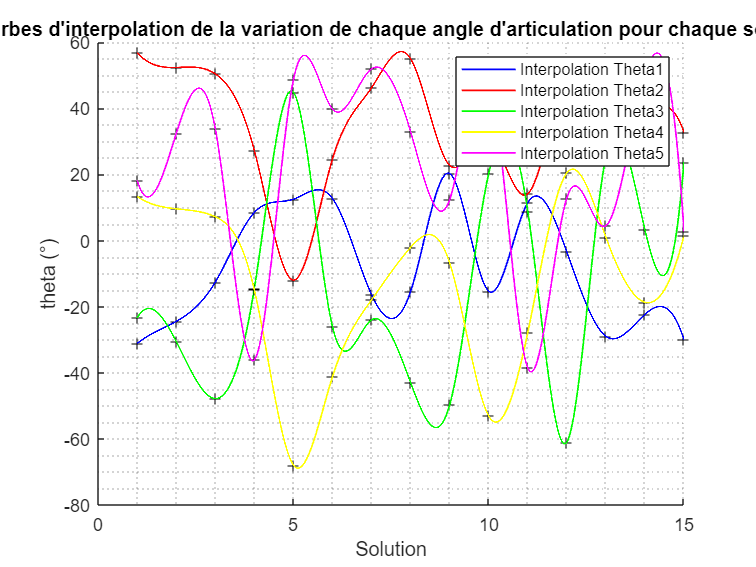

%Courbe de chaque angles 
% Créer une nouvelle figure
figure;

% Titre et étiquettes des axes
title('Courbes d''interpolation de la variation de chaque angle d''articulation pour chaque solution');
xlabel('Solution');
ylabel('theta (°)');
grid minor;
hold on; % Garder le graphique actif pour ajouter les données de chaque solution

% Boucle sur chaque angle d'articulation
for joint = 1:5
    % Tracer les valeurs des angles d'articulation pour chaque solution en convertissant les radians en degrés
    for i = 1:num_solutions
        % Extraire l'angle d'articulation ajusté pour cette solution
        theta_deg = all_solutions_deg(i, joint);
        % Tracer l'angle d'articulation pour cette solution avec un marqueur plein
        plot(i, theta_deg, '+', 'MarkerFaceColor', 'k', 'MarkerEdgeColor', 'k', 'HandleVisibility', 'off');

    end
    
    % Calculer une interpolation linéaire des données
    x_data = 1:num_solutions; % Les données x sont simplement les indices des solutions
    y_data = all_solutions_deg(:, joint); % Les données y sont les angles d'articulation convertis en degrés
    
    % Définir un ensemble de points plus fins pour l'interpolation
    finer_x = linspace(1, num_solutions, 10000); % 1000 points entre le premier et le dernier index
    
    % Calculer les valeurs interpolées
    interpolated_y = interp1(x_data, y_data, finer_x, 'spline');
    
    % Couleurs pour chaque angle d'articulation
    colors = ['b', 'r', 'g', 'y', 'm'];
    
    % Tracer la courbe d'interpolation
    plot(finer_x, interpolated_y, '-', 'DisplayName', ['Interpolation Theta', num2str(joint)], 'LineWidth', 1, 'Color', colors(joint));
end
        
legend("show")  

#### Positions des articulations pour chaque solution

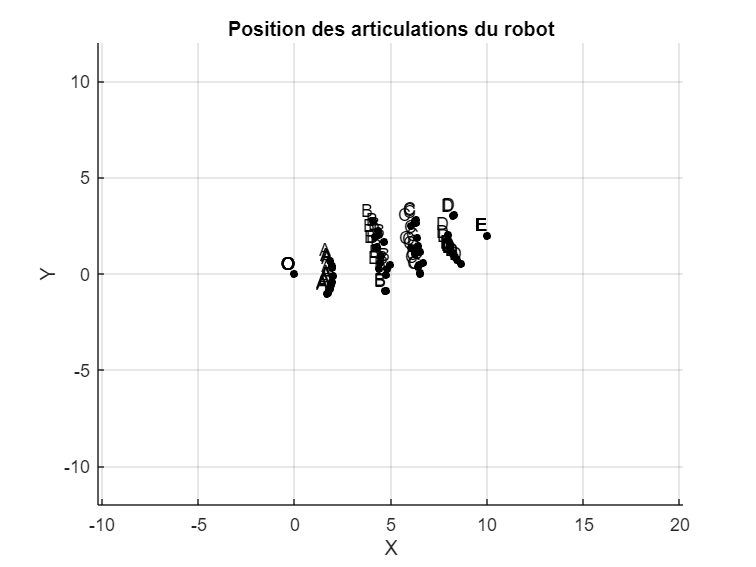

% Créer un graphique distinct pour les articulations du robot
figure;


hold on; % Garder le graphique actif pour ajouter les données de chaque solution


% Visualisation des configurations du robot
for i = 1:size(all_solutions, 1)
    % Extraire les angles d'articulation pour cette configuration
    theta1 = all_solutions(i, 1);
    theta2 = all_solutions(i, 2);
    theta3 = all_solutions(i, 3);
    theta4 = all_solutions(i, 4);
    theta5 = all_solutions(i, 5);

    % Calcul des positions des articulations du robot avec les valeurs des angles d'articulation calculées
    O = [0, 0]; % Position de l'origine
    A = [a1*cos(theta1), a1*sin(theta1)]; % Position de l'articulation A
    B = A + [a2*cos(theta1+theta2), a2*sin(theta1+theta2)]; % Position de l'articulation B
    C = B + [a3*cos(theta1+theta2+theta3), a3*sin(theta1+theta2+theta3)]; % Position de l'articulation C (extrémité de l'effecteur)
    D = C + [a4*cos(theta1+theta2+theta3+theta4), a4*sin(theta1+theta2+theta3+theta4)]; % Position de l'articulation C (extrémité de l'effecteur)
    E = D + [a5*cos(theta1+theta2+theta3+theta4+theta5), a5*sin(theta1+theta2+theta3+theta4+theta5)]; % Position de l'articulation C (extrémité de l'effecteur)

    % Tracer le robot pour cette configuration 
    scatter([O(1), A(1), B(1), C(1), D(1), E(1)], [O(2), A(2), B(2), C(2), D(2), E(2)], 20, 'k', 'filled', 'DisplayName', ['Articulations - Solution ', num2str(i)]); % Marques pour les articulations
    % Ajouter les noms des articulations
    text([O(1), A(1), B(1), C(1), D(1), E(1)], [O(2), A(2), B(2), C(2), D(2), E(2)], {'O', 'A', 'B', 'C', 'D', 'E'}, 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
end 
grid on;

% Calculer les limites des axes
xlim([-12, 12]); 
ylim([-12, 12]);
axis equal

% Configurer le titre et les étiquettes des axes
title('Position des articulations du robot');
xlabel('X');
ylabel('Y');

#### Graphique separe pour chaque articulation

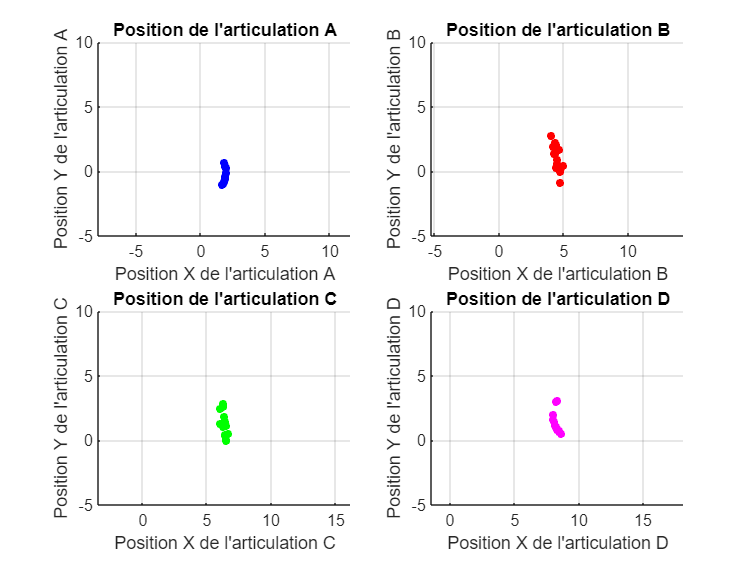

% Créer un graphique distinct pour chaque articulation
figure;

% Articulation A
subplot(2, 2, 1);
title('Position de l''articulation A');
xlabel('Position X de l''articulation A');
ylabel('Position Y de l''articulation A');
hold on;
% Calculer les positions de l'articulation A pour chaque solution
A_positions = zeros(size(all_solutions, 1), 2);
for i = 1:size(all_solutions, 1)
    % Extraire l'angle d'articulation pour cette configuration
    theta1 = all_solutions(i, 1);
    
    % Calculer la position de l'articulation A pour cette solution
    A = [a1*cos(theta1), a1*sin(theta1)]; % Position de l'articulation A
    A_positions(i, :) = A;
end
scatter(A_positions(:, 1), A_positions(:, 2), 20, 'b', 'filled');
grid on;
xlim([-5, 5]); % Définir les limites des axes X
ylim([-5, 10]); % Définir les limites des axes Y

% Articulation B
subplot(2, 2, 2);
title('Position de l''articulation B');
xlabel('Position X de l''articulation B');
ylabel('Position Y de l''articulation B');
hold on;
% Calculer les positions de l'articulation B pour chaque solution
B_positions = zeros(size(all_solutions, 1), 2);
for i = 1:size(all_solutions, 1)
    % Extraire les angles d'articulation pour cette configuration
    theta1 = all_solutions(i, 1);
    theta2 = all_solutions(i, 2);
    
    % Calculer la position de l'articulation B pour cette solution
    B = A_positions(i, :) + [a2*cos(theta1+theta2), a2*sin(theta1+theta2)]; % Position de l'articulation B
    B_positions(i, :) = B;
end
scatter(B_positions(:, 1), B_positions(:, 2), 20, 'r', 'filled');
grid on;
xlim([-5, 5]); % Définir les limites des axes X
ylim([-5, 10]); % Définir les limites des axes Y

% Articulation C
subplot(2, 2, 3);
title('Position de l''articulation C');
xlabel('Position X de l''articulation C');
ylabel('Position Y de l''articulation C');
hold on;
% Calculer les positions de l'articulation C pour chaque solution
C_positions = zeros(size(all_solutions, 1), 2);
for i = 1:size(all_solutions, 1)
    % Extraire les angles d'articulation pour cette configuration
    theta1 = all_solutions(i, 1);
    theta2 = all_solutions(i, 2);
    theta3 = all_solutions(i, 3);
    
    % Calculer la position de l'articulation C pour cette solution
    C = B_positions(i, :) + [a3*cos(theta1+theta2+theta3), a3*sin(theta1+theta2+theta3)]; % Position de l'articulation C
    C_positions(i, :) = C;
end
scatter(C_positions(:, 1), C_positions(:, 2), 20, 'g', 'filled');
grid on;
xlim([-5, 5]); % Définir les limites des axes X
ylim([-5, 10]); % Définir les limites des axes Y

% Articulation D
subplot(2, 2, 4);
title('Position de l''articulation D');
xlabel('Position X de l''articulation D');
ylabel('Position Y de l''articulation D');
hold on;
% Calculer les positions de l'articulation D pour chaque solution
D_positions = zeros(size(all_solutions, 1), 2);
for i = 1:size(all_solutions, 1)
    % Extraire les angles d'articulation pour cette configuration
    theta1 = all_solutions(i, 1);
    theta2 = all_solutions(i, 2);
    theta3 = all_solutions(i, 3);
    theta4 = all_solutions(i, 4);
    
    % Calculer la position de l'articulation D pour cette solution
    D = C_positions(i, :) + [a4*cos(theta1+theta2+theta3+theta4), a4*sin(theta1+theta2+theta3+theta4)]; % Position de l'articulation D
    D_positions(i, :) = D;
end
scatter(D_positions(:, 1), D_positions(:, 2), 20, 'm', 'filled');
grid on;
xlim([-5, 5]); % Définir les limites des axes X
ylim([-5, 10]); % Définir les limites des axes Y

% Réglage des espacements entre les sous-graphiques
subplot(2, 2, 1); axis equal; 
subplot(2, 2, 2); axis equal; 
subplot(2, 2, 3); axis equal; 
subplot(2, 2, 4); axis equal;

## Filtrage des solutions

### 1. Selon les butées des angles d'articulation


disp('SOLUTIONS FILTREES')

SOLUTIONS FILTREES


% Spécifier les intervalles d'angle souhaités
intervalles = [-30, 10; -90, 50; -90, 90; -90, 90; -90, 90]; % Par exemple, [-90, 90] pour tous les angles

% Créer un tri pour les solutions respectant les intervalles d'angle spécifiés
trisolution = all(all_solutions_deg >= intervalles(:, 1)' & all_solutions_deg <= intervalles(:, 2)', 2);

% Afficher toutes les configurations trouvées avec les angles ajustés
disp('Configurations possibles du robot dans l''intervalle [-180, 180] respectant les intervalles d''angle spécifiés:');

Configurations possibles du robot dans l'intervalle [-180, 180] respectant les intervalles d'angle spécifiés:


disp('    Theta1°   Theta2°   Theta3°   Theta4°   Theta5°   X_calculé   Y_calculé');

    Theta1°   Theta2°   Theta3°   Theta4°   Theta5°   X_calculé   Y_calculé


for i = 1:size(all_solutions_deg, 1)
    if trisolution(i)
        disp([all_solutions_deg(i, :), all_solutions(i, 6:7)]);
    else
        disp([sprintf('%9.2f   %9.2f   %9.2f   %9.2f   %9.2f', all_solutions_deg(i, :)), all_solutions(i, 6), all_solutions(i, 7)]);
    end
end

   -31.15       56.83      -23.39       13.37       18.21
□
   -24.45       52.39      -30.54        9.61       32.36
□
   -12.57       50.45      -47.82        7.20       33.84	□


    8.5033   27.2445  -14.4868  -14.9345  -36.1283   10.0000    2.0000



    12.51      -11.95       44.86      -67.94       48.61
□
    12.73       24.63      -26.04      -41.25       39.82
□


  -16.3645   46.2488  -24.0112  -17.9485   51.9600   10.0000    2.0000



   -15.42       55.03      -42.96       -2.07       32.98	□
    20.27       22.76      -49.75       -6.76       12.37
□


  -15.2840   31.0037   20.2784  -53.0669   51.3296   10.0000    2.0000



    11.45       14.14        8.88      -27.84      -38.50	□


   -3.4233   46.9613  -60.9867   20.4626   12.8728   10.0000    2.0000

  -28.9589   30.4184   25.2029    1.0189    4.5066   10.0000    2.0000

  -22.3496   36.3113    3.2690  -18.6660   49.7816   10.0000    2.0000



   -30.03       32.76       23.76        1.58        2.79	□



% Filtrer les solutions selon les intervalles d'angle spécifiés
solutions_filtrees = [];
for i = 1:size(all_solutions_deg, 1)
    if all(all_solutions_deg(i, :) >= intervalles(:, 1)' & all_solutions_deg(i, :) <= intervalles(:, 2)')
        solutions_filtrees = [solutions_filtrees; all_solutions_deg(i, :), all_solutions(i, 6:7)];
    end
end

% Afficher les configurations filtrées
disp('Configurations possibles du robot respectant les intervalles d''angle spécifiés:');

Configurations possibles du robot respectant les intervalles d'angle spécifiés:


disp('    Theta1°   Theta2°   Theta3°   Theta4°   Theta5°   X_calculé   Y_calculé');

    Theta1°   Theta2°   Theta3°   Theta4°   Theta5°   X_calculé   Y_calculé


disp(solutions_filtrees);

    8.5033   27.2445  -14.4868  -14.9345  -36.1283   10.0000    2.0000
  -16.3645   46.2488  -24.0112  -17.9485   51.9600   10.0000    2.0000
  -15.2840   31.0037   20.2784  -53.0669   51.3296   10.0000    2.0000
   -3.4233   46.9613  -60.9867   20.4626   12.8728   10.0000    2.0000
  -28.9589   30.4184   25.2029    1.0189    4.5066   10.0000    2.0000
  -22.3496   36.3113    3.2690  -18.6660   49.7816   10.0000    2.0000



### Affichage des solutions filtres

- Position des articulations du robot pour les solutions respectant les butees 

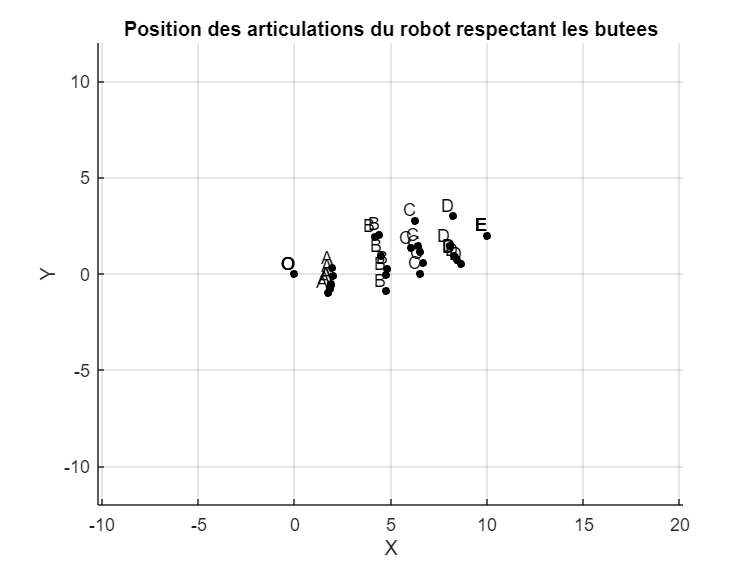

% Position darticulations du robot
figure;
hold on; % Garder le graphique actif pour ajouter les données de chaque solution
% Visualisation des configurations du robot pour les solutions filtrées uniquement
for i = 1:size(solutions_filtrees, 1)
    % Extraire les angles d'articulation pour cette configuration
    theta1 = solutions_filtrees(i, 1);
    theta2 = solutions_filtrees(i, 2);
    theta3 = solutions_filtrees(i, 3);
    theta4 = solutions_filtrees(i, 4);
    theta5 = solutions_filtrees(i, 5);

    % Calcul des positions des articulations du robot avec les valeurs des angles d'articulation calculées
    O = [0, 0]; % Position de l'origine
    A = [a1*cosd(theta1), a1*sind(theta1)]; % Position de l'articulation A
    B = A + [a2*cosd(theta1+theta2), a2*sind(theta1+theta2)]; % Position de l'articulation B
    C = B + [a3*cosd(theta1+theta2+theta3), a3*sind(theta1+theta2+theta3)]; % Position de l'articulation C (extrémité de l'effecteur)
    D = C + [a4*cosd(theta1+theta2+theta3+theta4), a4*sind(theta1+theta2+theta3+theta4)]; % Position de l'articulation C (extrémité de l'effecteur)
    E = D + [a5*cosd(theta1+theta2+theta3+theta4+theta5), a5*sind(theta1+theta2+theta3+theta4+theta5)]; % Position de l'articulation C (extrémité de l'effecteur)
    % Tracer le robot pour cette configuration 
    scatter([O(1), A(1), B(1), C(1), D(1), E(1)], [O(2), A(2), B(2), C(2), D(2), E(2)], 20, 'k', 'filled', 'DisplayName', ['Articulations - Solution ', num2str(i)]); % Marques pour les articulations
    % Ajouter les noms des articulations
    text([O(1), A(1), B(1), C(1), D(1), E(1)], [O(2), A(2), B(2), C(2), D(2), E(2)], {'O', 'A', 'B', 'C', 'D', 'E'}, 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
end
grid on;

% Calc2. uler les limites des axes
xlim([-12, 12]); 
ylim([-12, 12]);
axis equal

% Configurer le titre et les étiquettes des axes
title('Position des articulations du robot respectant les butees');
xlabel('X');
ylabel('Y');

2. Position de chaque articulation pour les solutions filtrees

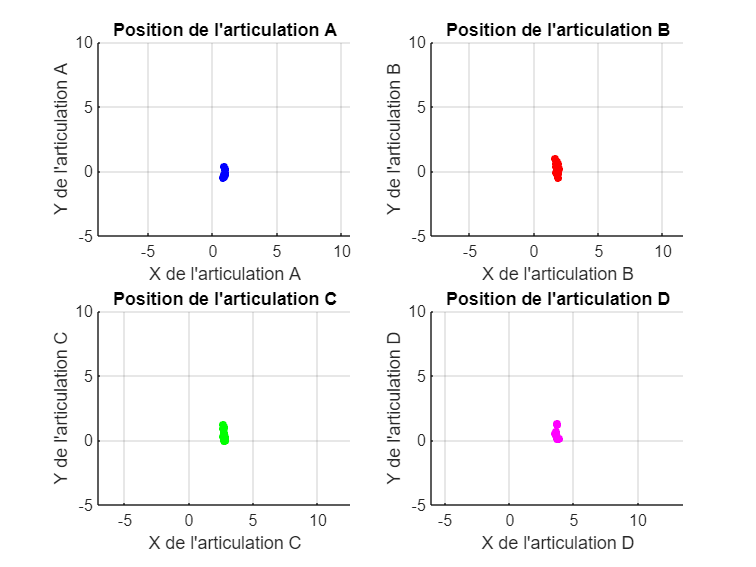

figure;
% Définition des titres et des labels
titles = {'A', 'B', 'C', 'D'};
xlabels = {'X de ', 'X de ', 'X de ', 'X de '};
ylabels = {'Y de ', 'Y de ', 'Y de ', 'Y de '};
colors = {'b', 'r', 'g', 'm'};

for joint = 1:4
    % Création du subplot
    subplot(2, 2, joint);
    title(['Position de l''articulation ', titles{joint}]);
    xlabel([xlabels{joint} 'l''articulation ' titles{joint}]);
    ylabel([ylabels{joint} 'l''articulation ' titles{joint}]);
    hold on;
    
    % Calcul des positions de l'articulation pour chaque solution
    joint_positions = zeros(size(all_solutions, 1), 2);
    for i = 1:size(all_solutions, 1)
        % Extraire les angles d'articulation pour cette configuration
        thetas = all_solutions(i, 1:joint);
        
        % Calculer la position de l'articulation pour cette solution
        position = [0, 0]; % Position de départ
        for k = 1:joint
            position = position + [cos(sum(thetas(1:k))), sin(sum(thetas(1:k)))];
        end
        joint_positions(i, :) = position;
    end
    
    % Tracer les positions
    scatter(joint_positions(:, 1), joint_positions(:, 2), 20, colors{joint}, 'filled');
    grid on;
    xlim([-5, 5]); % Définir les limites des axes X
    ylim([-5, 10]); % Définir les limites des axes Y
    
    % Réglage de l'espacement entre les sous-graphiques
    axis equal;
end

function drawSegmentRectangle(startPoint, endPoint, rectWidth, color)
    % Calcule la longueur et l'angle du segment
    segmentLength = norm(endPoint - startPoint);
    segmentAngle = atan2(endPoint(2) - startPoint(2), endPoint(1) - startPoint(1));
    
    % Calcule les coordonnées des coins du rectangle
    dx = rectWidth * cos(segmentAngle + pi/2);
    dy = rectWidth * sin(segmentAngle + pi/2);
    rectPoints = [startPoint(1) - dx, startPoint(2) - dy;
                  startPoint(1) + dx, startPoint(2) + dy;
                  endPoint(1) + dx, endPoint(2) + dy;
                  endPoint(1) - dx, endPoint(2) - dy;
                  startPoint(1) - dx, startPoint(2) - dy];
    
    % Trace le rectangle
    fill(rectPoints(:, 1), rectPoints(:, 2), color, 'EdgeColor', color, 'FaceAlpha', 0.5);
end